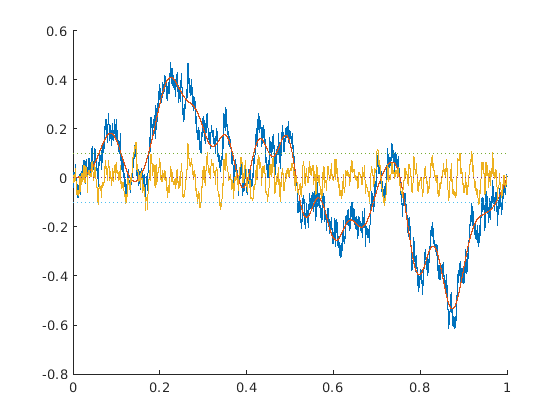

% Parameters
time = 1;
timestep = 0.0001;
eps = 0.0001;
n = round(time/timestep);
four_depth = n/10;

clf
hold on

% Create and plot periodic Wiener process
Ws = zeros(n + 1, 1);
for step = 0:(n - 1)
    Ws(step + 2) = (1 - 1/(n - step))*Ws(step + 1) + sqrt(timestep*(1 - 1/(n - step)))*normrnd(0, 1);
end
Ts = linspace(0, time, n + 1)';
plot(Ts, Ws);

% Find Fourier series coefficients
sin_coeffs = zeros(four_depth, 1);
for four_ind = 1:four_depth
    sin_coeffs(four_ind) = 2/time*timestep*sum(Ws.*sin(pi*four_ind*Ts/time));
end
% Plot mean and perturbation
four_depth_mean = floor(time/(pi*sqrt(eps)));
plot(Ts, sin(pi*Ts*linspace(1, four_depth_mean, four_depth_mean)/time)*sin_coeffs(1:four_depth_mean));
plot(Ts, sin(pi*Ts*linspace(four_depth_mean + 1, four_depth, four_depth - four_depth_mean)/time)*sin_coeffs((four_depth_mean + 1):four_depth));

% Plot 0 line
plot([0, time], 0*[1, 1], ':');
% Plot +-eps^(1/4) lines
plot([0, time], + eps^(1/4)*[1, 1], ':');
plot([0, time], - eps^(1/4)*[1, 1], ':');

hold off